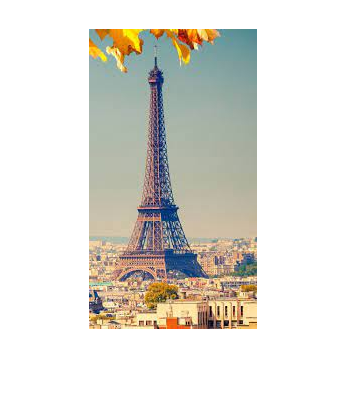

img = imread("Tower.jpg");
imshow(img)

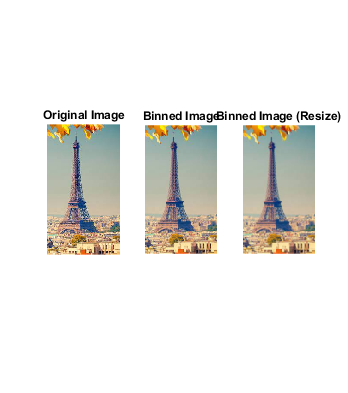


binningFactor = 2;

redChannel = img(:,:,1);
greenChannel = img(:,:,2);
blueChannel = img(:,:,3);

redBinned = blockproc(redChannel, [binningFactor binningFactor], @(block) mean(block.data(:)), 'PadPartialBlocks', true);
greenBinned = blockproc(greenChannel, [binningFactor binningFactor], @(block) mean(block.data(:)), 'PadPartialBlocks', true);
blueBinned = blockproc(blueChannel, [binningFactor binningFactor], @(block) mean(block.data(:)), 'PadPartialBlocks', true);

bin_img = cat(3, redBinned, greenBinned, blueBinned);

subplot(1, 3, 1);
imshow(img);
title('Original Image');

subplot(1, 3, 2);
imshow(uint8(bin_img));
title('Binned Image');

bin_img_resize = imresize(img, 1/binningFactor, "bilinear");
subplot(1, 3, 3);
imshow(uint8(bin_img_resize));
title('Binned Image (Resize)');


isEqual = isequal(uint8(bin_img), bin_img_resize);
uint8(bin_img);
bin_img_resize;